cd('/Volumes/ChenLabHDDB/FLP/0429AchsensorEEGEMG003')
ExperimentName='0429AchsensorEEGEMG003'; % Give a specific name to this experiment or this analysis
FirstAcq=13; % What's the acquisition number of the first offical recording
number_of_acq = 24; % How many chunks of recordings are there?
Dark_hours=[13 14 15 16 17 18 19 20 21 22 23 24]

Dark_hours =     13    14    15    16    17    18    19    20    21    22    23    24


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 


for i=1:number_of_acq
    
    load([FLPfiles num2str(i+FirstAcq-1) '.mat']);
    filename=[analysis_name,num2str(i),'h_20220513.mat'];
    FLiPAnalysis_Tau_p1_Photon(FLPdata_time, FLPdata_lifetimes, timebin,ch, filename)
    load(filename);
    
    time(isnan(time))=[];
    photoncount(isnan(photoncount))=[];
    tau_avg(isnan(tau_avg))=[];
    tau_avgTrunc(isnan(tau_avgTrunc))=[];
    tau_empTrunc(isnan(tau_empTrunc))=[];
    p1(isnan(p1))=[];
    chi2(isnan(chi2))=[];

    save(filename, 'time','photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1','chi2','beta2','beta4','beta5','beta6','lifetime_histograms');

    
end

analysis_name=[ExperimentName,'_analysis_'];
FLPfiles='continuous aquistion data_'; 
starting_reference_file=dir([ExperimentName,'FLIM001.mat'])

starting_reference_file = struct with fields:
       name: '0429AchsensorEEGEMG003FLIM001.mat'
     folder: '/Volumes/ChenLabHDDB/FLP/0429AchsensorEEGEMG003'
       date: '29-Apr-2021 18:43:29'
      bytes: 2974
      isdir: 0
    datenum: 7.3828e+05


starting_reference_time=datetime(starting_reference_file.date);
SixClockNorm=datetime(starting_reference_time.Year,starting_reference_time.Month, starting_reference_time.Day-1,18,0,0);

tau_empTrunc_all_dark=[];
tau_avg_all_dark=[];
tau_empTrunc_all_DC_dark=[];
tau_avg_all_DC_dark=[];
tau_empTrunc_all_AC_dark=[];
tau_avg_all_AC_dark=[];
intensity_all_dark=[];
intensity_all_DC_dark=[];
intensity_all_AC_dark=[];
time_z_all_dark=[];
states_all_dark=[];
peak_channels_all=[];
lifetime_histograms_all=[];

for i=1:size(Dark_hours,2)
    filename=[analysis_name,num2str(Dark_hours(i)-FirstAcq+1),'h_20220513.mat'];
    load(filename);
    peak_channels = FindPeakChannels(lifetime_histograms);
    peak_channels_all=[peak_channels_all peak_channels];
    lifetime_histograms_all=[lifetime_histograms_all lifetime_histograms];

    order=6;
    Nyquist=0.5*3489/3600;% Nyquist rate -- half the sample rate.
    CutoffLow=0.01;
    normalizedCutoffLow = CutoffLow / Nyquist;
    [b1,a1]=butter(order,normalizedCutoffLow,'low');

    tau_empTrunc_DC=filtfilt(b1,a1,tau_empTrunc);
    tau_avg_DC=filtfilt(b1,a1,tau_avg);
    intensity_DC=filtfilt(b1,a1,photoncount);

%     figure
%     plot(time, signal_to_filter);
%     hold on
%     plot(time, tau_empTrunc_DC);


    CutoffHigh=0.01;
    normalizedCutoffHigh = CutoffHigh / Nyquist;
    [b2,a2]=butter(order,normalizedCutoffHigh,'high');

    tau_empTrunc_AC=filtfilt(b2,a2,tau_empTrunc);
    tau_avg_AC=filtfilt(b2,a2,tau_avg);
    intensity_AC=filtfilt(b2,a2,photoncount);

    rawfile=dir([FLPfiles num2str(Dark_hours(i)) '.mat']);
    reference_time=datetime(rawfile.date);
    time_z=seconds(reference_time-SixClockNorm)+(time-max(time));


    tau_empTrunc_all_dark=[tau_empTrunc_all_dark; tau_empTrunc];
    tau_avg_all_dark=[tau_avg_all_dark; tau_avg];
    tau_empTrunc_all_DC_dark=[tau_empTrunc_all_DC_dark; tau_empTrunc_DC];
    tau_avg_all_DC_dark=[tau_avg_all_DC_dark; tau_avg_DC];
    tau_empTrunc_all_AC_dark=[tau_empTrunc_all_AC_dark; tau_empTrunc_AC];
    tau_avg_all_AC_dark=[tau_avg_all_AC_dark; tau_avg_AC];
    intensity_all_dark=[intensity_all_dark; photoncount];
    intensity_all_DC_dark=[intensity_all_DC_dark; intensity_DC];
    intensity_all_AC_dark=[intensity_all_AC_dark; intensity_AC];
    time_z_all_dark=[time_z_all_dark; time_z];

end

for i=1:size(time_z_all_dark,1)
    if time_z_all_dark(i)>86400
        time_z_all_dark(i)=time_z_all_dark(i)-86400;
    end
end



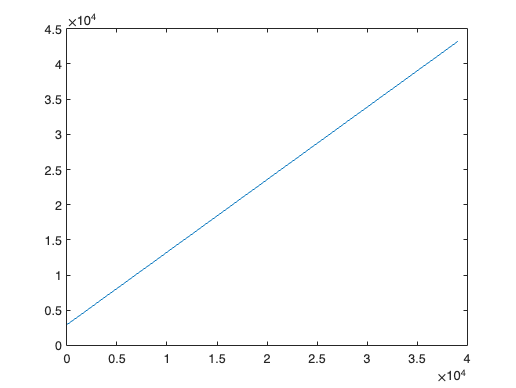

if darktime_calc==1
    for i=1:(size(time_z_all_dark, 1)-1)
        if time_z_all_dark(i+1)-time_z_all_dark(i)<0
            break
        end
        ReOrder=[i+1:1:size(time_z_all_dark, 1) 1:1:i];
    end
    
    darks=find(time_z_all_dark>=0 & time_z_all_dark<=43200);
    darkonly=time_z_all_dark(darks);
    
    for j=1:(size(darkonly,1)-1)
        if darkonly(j+1)-darkonly(j)<0
            break
        end
    end

    dark_acqs=[i+1:1:size(time_z_all_dark, 1) 1:1:j];
end

if darktime_calc==0
    dark_acqs=find(time_z_all_dark>=0 & time_z_all_dark<=43200);
end


tau_empTrunc_all_darkonly = tau_empTrunc_all_dark(dark_acqs);
tau_avg_all_darkonly= tau_avg_all_dark(dark_acqs);
tau_empTrunc_all_darkonly = tau_empTrunc_all_DC_dark(dark_acqs);
tau_avg_all_DC_darkonly = tau_avg_all_DC_dark(dark_acqs);
tau_empTrunc_all_AC_darkonly = tau_empTrunc_all_AC_dark(dark_acqs);
tau_avg_all_AC_darkonly = tau_avg_all_AC_dark(dark_acqs);
intensity_all_darkonly = intensity_all_dark(dark_acqs);
intensity_all_darkonly = intensity_all_DC_dark(dark_acqs);
intensity_all_AC_darkonly = intensity_all_AC_dark(dark_acqs);
time_z_all_darkonly = time_z_all_dark(dark_acqs);

figure
plot(time_z_all_darkonly)

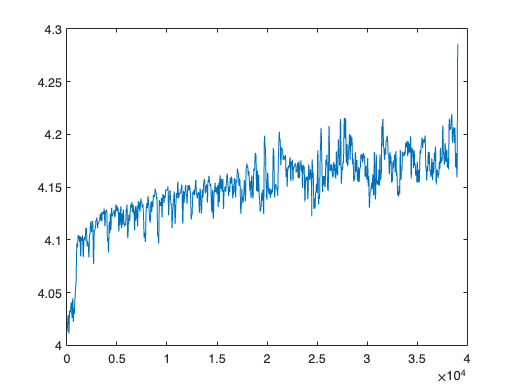

figure
plot(tau_empTrunc_all_darkonly)

cd('/Volumes/ChenLabHDDB/FLP/0502AchsensorEEGEMG005_BLA')
ExperimentName='0502AchsensorEEGEMG005'; % Give a specific name to this experiment or this analysis
FirstAcq=10; % What's the acquisition number of the first offical recording
number_of_acq = 24; % How many chunks of recordings are there?
Dark_hours=[12 13 14 15 16 17 18 19 20 21 22 23 24]

Dark_hours =     12    13    14    15    16    17    18    19    20    21    22    23    24


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 


for i=1:number_of_acq
    
    load([FLPfiles num2str(i+FirstAcq-1) '.mat']);
    filename=[analysis_name,num2str(i),'h_20220513.mat'];
    FLiPAnalysis_Tau_p1_Photon(FLPdata_time, FLPdata_lifetimes, timebin,ch, filename)
    load(filename);
    
    time(isnan(time))=[];
    photoncount(isnan(photoncount))=[];
    tau_avg(isnan(tau_avg))=[];
    tau_avgTrunc(isnan(tau_avgTrunc))=[];
    tau_empTrunc(isnan(tau_empTrunc))=[];
    p1(isnan(p1))=[];
    chi2(isnan(chi2))=[];

    save(filename, 'time','photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1','chi2','beta2','beta4','beta5','beta6','lifetime_histograms');

    
end

analysis_name=[ExperimentName,'_analysis_'];
FLPfiles='continuous aquistion data_'; 
starting_reference_file=dir([ExperimentName,'FLIM001.mat'])

starting_reference_file = struct with fields:
       name: '0502AchsensorEEGEMG005FLIM001.mat'
     folder: '/Volumes/ChenLabHDDB/FLP/0502AchsensorEEGEMG005_BLA'
       date: '02-May-2021 15:53:40'
      bytes: 3061
      isdir: 0
    datenum: 7.3828e+05


starting_reference_time=datetime(starting_reference_file.date);
SixClockNorm=datetime(starting_reference_time.Year,starting_reference_time.Month, starting_reference_time.Day-1,18,0,0);

tau_empTrunc_all_dark=[];
tau_avg_all_dark=[];
tau_empTrunc_all_DC_dark=[];
tau_avg_all_DC_dark=[];
tau_empTrunc_all_AC_dark=[];
tau_avg_all_AC_dark=[];
intensity_all_dark=[];
intensity_all_DC_dark=[];
intensity_all_AC_dark=[];
time_z_all_dark=[];
states_all_dark=[];
peak_channels_all=[];
lifetime_histograms_all=[];

for i=1:size(Dark_hours,2)
    filename=[analysis_name,num2str(Dark_hours(i)-FirstAcq+1),'h_20220513.mat'];
    load(filename);
    peak_channels = FindPeakChannels(lifetime_histograms);
    peak_channels_all=[peak_channels_all peak_channels];
    lifetime_histograms_all=[lifetime_histograms_all lifetime_histograms];

    order=6;
    Nyquist=0.5*3489/3600;% Nyquist rate -- half the sample rate.
    CutoffLow=0.01;
    normalizedCutoffLow = CutoffLow / Nyquist;
    [b1,a1]=butter(order,normalizedCutoffLow,'low');

    tau_empTrunc_DC=filtfilt(b1,a1,tau_empTrunc);
    tau_avg_DC=filtfilt(b1,a1,tau_avg);
    intensity_DC=filtfilt(b1,a1,photoncount);

%     figure
%     plot(time, signal_to_filter);
%     hold on
%     plot(time, tau_empTrunc_DC);


    CutoffHigh=0.01;
    normalizedCutoffHigh = CutoffHigh / Nyquist;
    [b2,a2]=butter(order,normalizedCutoffHigh,'high');

    tau_empTrunc_AC=filtfilt(b2,a2,tau_empTrunc);
    tau_avg_AC=filtfilt(b2,a2,tau_avg);
    intensity_AC=filtfilt(b2,a2,photoncount);

    rawfile=dir([FLPfiles num2str(Dark_hours(i)) '.mat']);
    reference_time=datetime(rawfile.date);
    time_z=seconds(reference_time-SixClockNorm)+(time-max(time));


    tau_empTrunc_all_dark=[tau_empTrunc_all_dark; tau_empTrunc];
    tau_avg_all_dark=[tau_avg_all_dark; tau_avg];
    tau_empTrunc_all_DC_dark=[tau_empTrunc_all_DC_dark; tau_empTrunc_DC];
    tau_avg_all_DC_dark=[tau_avg_all_DC_dark; tau_avg_DC];
    tau_empTrunc_all_AC_dark=[tau_empTrunc_all_AC_dark; tau_empTrunc_AC];
    tau_avg_all_AC_dark=[tau_avg_all_AC_dark; tau_avg_AC];
    intensity_all_dark=[intensity_all_dark; photoncount];
    intensity_all_DC_dark=[intensity_all_DC_dark; intensity_DC];
    intensity_all_AC_dark=[intensity_all_AC_dark; intensity_AC];
    time_z_all_dark=[time_z_all_dark; time_z];

end

for i=1:size(time_z_all_dark,1)
    if time_z_all_dark(i)>86400
        time_z_all_dark(i)=time_z_all_dark(i)-86400;
    end
end



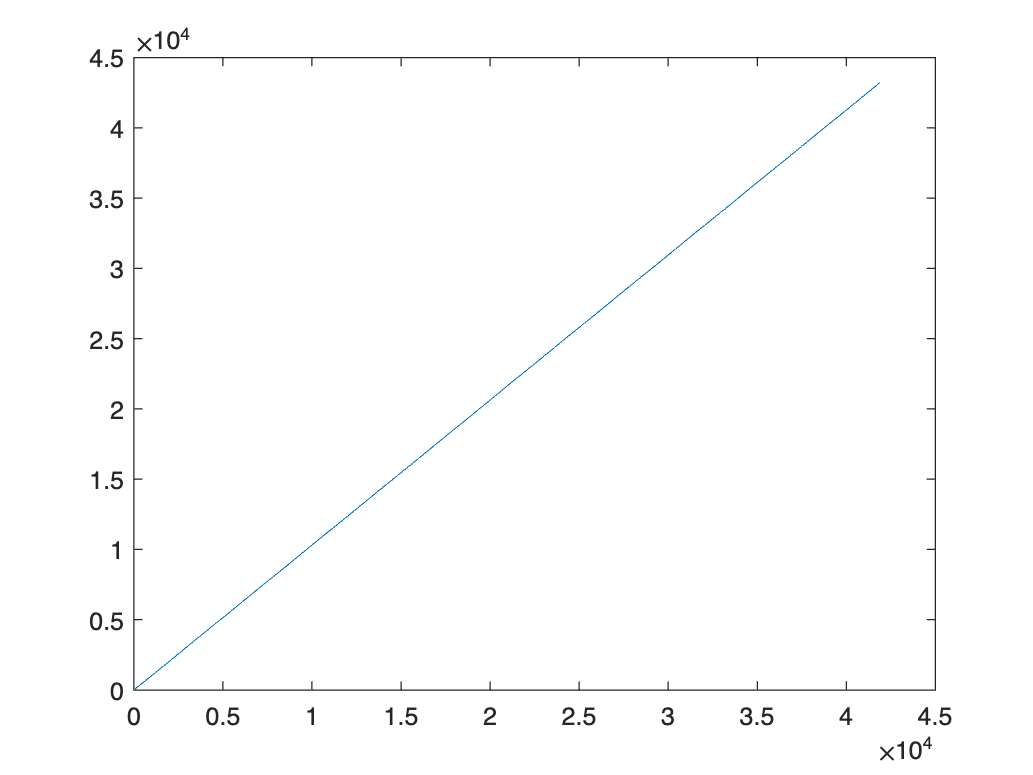

if darktime_calc==1
    for i=1:(size(time_z_all_dark, 1)-1)
        if time_z_all_dark(i+1)-time_z_all_dark(i)<0
            break
        end
        ReOrder=[i+1:1:size(time_z_all_dark, 1) 1:1:i];
    end
    
    darks=find(time_z_all_dark>=0 & time_z_all_dark<=43200);
    darkonly=time_z_all_dark(darks);
    
    for j=1:(size(darkonly,1)-1)
        if darkonly(j+1)-darkonly(j)<0
            break
        end
    end

    dark_acqs=[i+1:1:size(time_z_all_dark, 1) 1:1:j];
end

if darktime_calc==0
    dark_acqs=find(time_z_all_dark>=0 & time_z_all_dark<=43200);
end


tau_empTrunc_all_darkonly = tau_empTrunc_all_dark(dark_acqs);
tau_avg_all_darkonly= tau_avg_all_dark(dark_acqs);
tau_empTrunc_all_darkonly = tau_empTrunc_all_DC_dark(dark_acqs);
tau_avg_all_DC_darkonly = tau_avg_all_DC_dark(dark_acqs);
tau_empTrunc_all_AC_darkonly = tau_empTrunc_all_AC_dark(dark_acqs);
tau_avg_all_AC_darkonly = tau_avg_all_AC_dark(dark_acqs);
intensity_all_darkonly = intensity_all_dark(dark_acqs);
intensity_all_darkonly = intensity_all_DC_dark(dark_acqs);
intensity_all_AC_darkonly = intensity_all_AC_dark(dark_acqs);
time_z_all_darkonly = time_z_all_dark(dark_acqs);

figure
plot(time_z_all_darkonly)

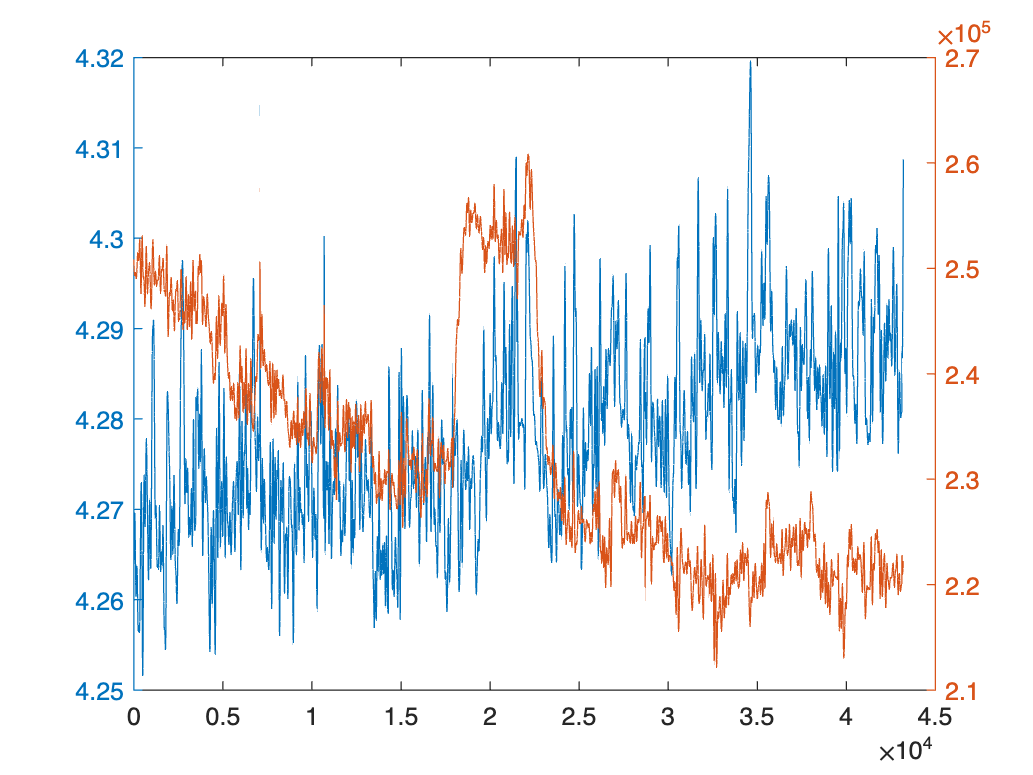

figure
yyaxis left
plot(time_z_all_darkonly,tau_empTrunc_all_darkonly)
yyaxis right
plot(time_z_all_darkonly,intensity_all_darkonly)

cd('/Volumes/ChenLabHDDB/FLP/0504AchsensorEEGEMG007_BLA')
ExperimentName='0504AchsensorEEGEMG007'; % Give a specific name to this experiment or this analysis
FirstAcq=10; % What's the acquisition number of the first offical recording
number_of_acq = 24; % How many chunks of recordings are there?
Dark_hours=[10 11 12 13 14 15 16 17 18 19 20 21]

Dark_hours =     10    11    12    13    14    15    16    17    18    19    20    21


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 


for i=1:number_of_acq
    
    load([FLPfiles num2str(i+FirstAcq-1) '.mat']);
    filename=[analysis_name,num2str(i),'h_20220513.mat'];
    FLiPAnalysis_Tau_p1_Photon(FLPdata_time, FLPdata_lifetimes, timebin,ch, filename)
    load(filename);
    
    time(isnan(time))=[];
    photoncount(isnan(photoncount))=[];
    tau_avg(isnan(tau_avg))=[];
    tau_avgTrunc(isnan(tau_avgTrunc))=[];
    tau_empTrunc(isnan(tau_empTrunc))=[];
    p1(isnan(p1))=[];
    chi2(isnan(chi2))=[];

    save(filename, 'time','photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1','chi2','beta2','beta4','beta5','beta6','lifetime_histograms');

    
end

analysis_name=[ExperimentName,'_analysis_'];
FLPfiles='continuous aquistion data_'; 
starting_reference_file=dir([ExperimentName,'FLIM001.mat'])

starting_reference_file = struct with fields:
       name: '0504AchsensorEEGEMG007FLIM001.mat'
     folder: '/Volumes/ChenLabHDDB/FLP/0504AchsensorEEGEMG007_BLA'
       date: '04-May-2021 18:28:44'
      bytes: 2996
      isdir: 0
    datenum: 7.3828e+05


starting_reference_time=datetime(starting_reference_file.date);
SixClockNorm=datetime(starting_reference_time.Year,starting_reference_time.Month, starting_reference_time.Day-1,18,0,0);

tau_empTrunc_all_dark=[];
tau_avg_all_dark=[];
tau_empTrunc_all_DC_dark=[];
tau_avg_all_DC_dark=[];
tau_empTrunc_all_AC_dark=[];
tau_avg_all_AC_dark=[];
intensity_all_dark=[];
intensity_all_DC_dark=[];
intensity_all_AC_dark=[];
time_z_all_dark=[];
states_all_dark=[];
peak_channels_all=[];
lifetime_histograms_all=[];

for i=1:size(Dark_hours,2)
    filename=[analysis_name,num2str(Dark_hours(i)-FirstAcq+1),'h_20220513.mat'];
    load(filename);
    peak_channels = FindPeakChannels(lifetime_histograms);
    peak_channels_all=[peak_channels_all peak_channels];
    lifetime_histograms_all=[lifetime_histograms_all lifetime_histograms];

    order=6;
    Nyquist=0.5*3489/3600;% Nyquist rate -- half the sample rate.
    CutoffLow=0.01;
    normalizedCutoffLow = CutoffLow / Nyquist;
    [b1,a1]=butter(order,normalizedCutoffLow,'low');

    tau_empTrunc_DC=filtfilt(b1,a1,tau_empTrunc);
    tau_avg_DC=filtfilt(b1,a1,tau_avg);
    intensity_DC=filtfilt(b1,a1,photoncount);

%     figure
%     plot(time, signal_to_filter);
%     hold on
%     plot(time, tau_empTrunc_DC);


    CutoffHigh=0.01;
    normalizedCutoffHigh = CutoffHigh / Nyquist;
    [b2,a2]=butter(order,normalizedCutoffHigh,'high');

    tau_empTrunc_AC=filtfilt(b2,a2,tau_empTrunc);
    tau_avg_AC=filtfilt(b2,a2,tau_avg);
    intensity_AC=filtfilt(b2,a2,photoncount);

    rawfile=dir([FLPfiles num2str(Dark_hours(i)) '.mat']);
    reference_time=datetime(rawfile.date);
    time_z=seconds(reference_time-SixClockNorm)+(time-max(time));


    tau_empTrunc_all_dark=[tau_empTrunc_all_dark; tau_empTrunc];
    tau_avg_all_dark=[tau_avg_all_dark; tau_avg];
    tau_empTrunc_all_DC_dark=[tau_empTrunc_all_DC_dark; tau_empTrunc_DC];
    tau_avg_all_DC_dark=[tau_avg_all_DC_dark; tau_avg_DC];
    tau_empTrunc_all_AC_dark=[tau_empTrunc_all_AC_dark; tau_empTrunc_AC];
    tau_avg_all_AC_dark=[tau_avg_all_AC_dark; tau_avg_AC];
    intensity_all_dark=[intensity_all_dark; photoncount];
    intensity_all_DC_dark=[intensity_all_DC_dark; intensity_DC];
    intensity_all_AC_dark=[intensity_all_AC_dark; intensity_AC];
    time_z_all_dark=[time_z_all_dark; time_z];

end

for i=1:size(time_z_all_dark,1)
    if time_z_all_dark(i)>86400
        time_z_all_dark(i)=time_z_all_dark(i)-86400;
    end
end



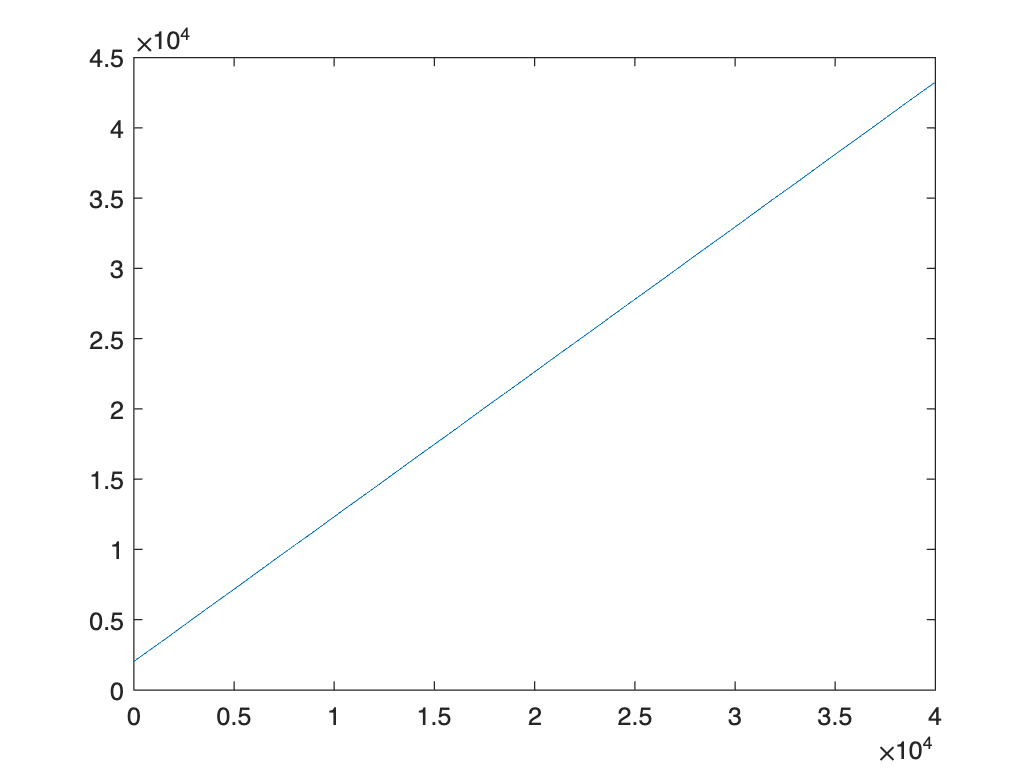

if darktime_calc==1
    for i=1:(size(time_z_all_dark, 1)-1)
        if time_z_all_dark(i+1)-time_z_all_dark(i)<0
            break
        end
        ReOrder=[i+1:1:size(time_z_all_dark, 1) 1:1:i];
    end
    
    darks=find(time_z_all_dark>=0 & time_z_all_dark<=43200);
    darkonly=time_z_all_dark(darks);
    
    for j=1:(size(darkonly,1)-1)
        if darkonly(j+1)-darkonly(j)<0
            break
        end
    end

    dark_acqs=[i+1:1:size(time_z_all_dark, 1) 1:1:j];
end

if darktime_calc==0
    dark_acqs=find(time_z_all_dark>=0 & time_z_all_dark<=43200);
end


tau_empTrunc_all_darkonly = tau_empTrunc_all_dark(dark_acqs);
tau_avg_all_darkonly= tau_avg_all_dark(dark_acqs);
tau_empTrunc_all_darkonly = tau_empTrunc_all_DC_dark(dark_acqs);
tau_avg_all_DC_darkonly = tau_avg_all_DC_dark(dark_acqs);
tau_empTrunc_all_AC_darkonly = tau_empTrunc_all_AC_dark(dark_acqs);
tau_avg_all_AC_darkonly = tau_avg_all_AC_dark(dark_acqs);
intensity_all_darkonly = intensity_all_dark(dark_acqs);
intensity_all_darkonly = intensity_all_DC_dark(dark_acqs);
intensity_all_AC_darkonly = intensity_all_AC_dark(dark_acqs);
time_z_all_darkonly = time_z_all_dark(dark_acqs);

figure
plot(time_z_all_darkonly)

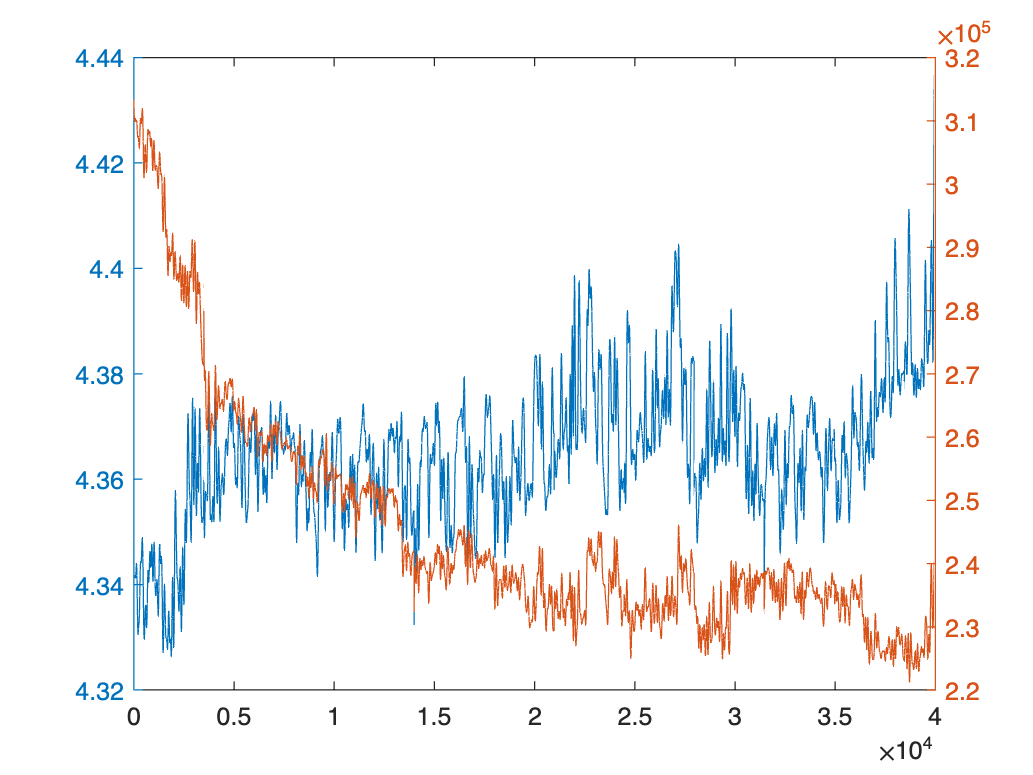

figure
yyaxis left
plot(tau_empTrunc_all_darkonly)
yyaxis right
plot(intensity_all_darkonly)